tic
syms t s  y(t) Y
figure; hold on
eqn1 = diff(y,2)+ diff(y)+y(t)==((t+1)^3)*exp(-t)*cos(t)*sin(3*t);
lteqn1 = laplace(eqn1, t, s)

$$lteqn1 = \begin{array}{l} s\,\sigma_{1}-y\left(0\right)-s\,y\left(0\right)+s^{2}\,\sigma_{1}-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+\sigma_{1}=\frac{2\,s^{6}+24\,s^{5}+150\,s^{4}+544\,s^{3}+1134\,s^{2}+1128\,s+346}{2\,\left(s^{8}+8\,s^{7}+44\,s^{6}+152\,s^{5}+406\,s^{4}+760\,s^{3}+1100\,s^{2}+1000\,s+625\right)}+\frac{4\,s^{6}+48\,s^{5}+444\,s^{4}+2240\,s^{3}+8316\,s^{2}+16080\,s+19844}{2\,\left(s^{8}+8\,s^{7}+92\,s^{6}+440\,s^{5}+2566\,s^{4}+7480\,s^{3}+26588\,s^{2}+39304\,s+83521\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{laplace}\left(y\left(t\right),t,s\right) \end{array}$$

neweqn1 = subs(lteqn1, [laplace(y(t),t,s), y(0), subs(diff(y(t),t),t,0)], [Y, 1, 0])

$$neweqn1 = Y-s+Y\,s+Y\,s^{2}-1=\frac{2\,s^{6}+24\,s^{5}+150\,s^{4}+544\,s^{3}+1134\,s^{2}+1128\,s+346}{2\,\left(s^{8}+8\,s^{7}+44\,s^{6}+152\,s^{5}+406\,s^{4}+760\,s^{3}+1100\,s^{2}+1000\,s+625\right)}+\frac{4\,s^{6}+48\,s^{5}+444\,s^{4}+2240\,s^{3}+8316\,s^{2}+16080\,s+19844}{2\,\left(s^{8}+8\,s^{7}+92\,s^{6}+440\,s^{5}+2566\,s^{4}+7480\,s^{3}+26588\,s^{2}+39304\,s+83521\right)}$$

ytrans1 = simplify(solve(neweqn1, Y))

$$ytrans1 = \frac{s^{17}+17\,s^{16}+216\,s^{15}+1883\,s^{14}+13496\,s^{13}+77881\,s^{12}+382776\,s^{11}+1585099\,s^{10}+5657314\,s^{9}+17221099\,s^{8}+45092776\,s^{7}+100147529\,s^{6}+188387568\,s^{5}+292748555\,s^{4}+368303432\,s^{3}+351557137\,s^{2}+229139061\,s+72851008}{\left(s^{2}+s+1\right)\,{\left(s^{4}+4\,s^{3}+26\,s^{2}+44\,s+85\right)}^{4}}$$

y1 = ilaplace(ytrans1, s, t)

$$y1 = \begin{array}{l} \frac{208760666888776\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\sigma_{1}\right)+\frac{7300078871912\,\sqrt{3}\,\sin\left(\sigma_{1}\right)}{78285250083291}\right)}{96347750544721}-\frac{{\mathrm{e}}^{-t}\,\left(60\,t\,\cos\left(4\,t\right)-15\,\sin\left(4\,t\right)-45\,t\,\sin\left(4\,t\right)+180\,t^{2}\,\cos\left(4\,t\right)-64\,t^{3}\,\cos\left(4\,t\right)+96\,t^{2}\,\sin\left(4\,t\right)+240\,t^{3}\,\sin\left(4\,t\right)\right)}{7712}-\frac{3\,{\mathrm{e}}^{-t}\,\left(336\,t\,\cos\left(2\,t\right)-168\,\sin\left(2\,t\right)+27\,t\,\sin\left(2\,t\right)-54\,t^{2}\,\cos\left(2\,t\right)+224\,t^{2}\,\sin\left(2\,t\right)\right)}{1352}-\frac{3\,{\mathrm{e}}^{-t}\,\left(46608\,t\,\cos\left(4\,t\right)-11652\,\sin\left(4\,t\right)+303\,t\,\sin\left(4\,t\right)-1212\,t^{2}\,\cos\left(4\,t\right)+62144\,t^{2}\,\sin\left(4\,t\right)\right)}{1858592}-\frac{3\,{\mathrm{e}}^{-t}\,\left(766\,t\,\cos\left(2\,t\right)-383\,\sin\left(2\,t\right)+5312\,t\,\sin\left(2\,t\right)\right)}{17576}-\frac{3\,{\mathrm{e}}^{-t}\,\left(737948\,t\,\cos\left(4\,t\right)-184487\,\sin\left(4\,t\right)+15439040\,t\,\sin\left(4\,t\right)\right)}{447920672}-\frac{31973\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\frac{7665\,\sin\left(2\,t\right)}{63946}\right)}{28561}-\frac{{\mathrm{e}}^{-t}\,\left(30\,t\,\cos\left(2\,t\right)-15\,\sin\left(2\,t\right)-9\,t\,\sin\left(2\,t\right)+18\,t^{2}\,\cos\left(2\,t\right)-8\,t^{3}\,\cos\left(2\,t\right)+24\,t^{2}\,\sin\left(2\,t\right)+12\,t^{3}\,\sin\left(2\,t\right)\right)}{104}-\frac{159487282\,{\mathrm{e}}^{-t}\,\left(\cos\left(4\,t\right)+\frac{199148625\,\sin\left(4\,t\right)}{318974564}\right)}{3373402561}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,t}{2} \end{array}$$

p17partB = ezplot(y1, [0 15])

p17partB =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×434 double]
              YData: [1×434 double]
              ZData: [1×0 double]

  Show all properties


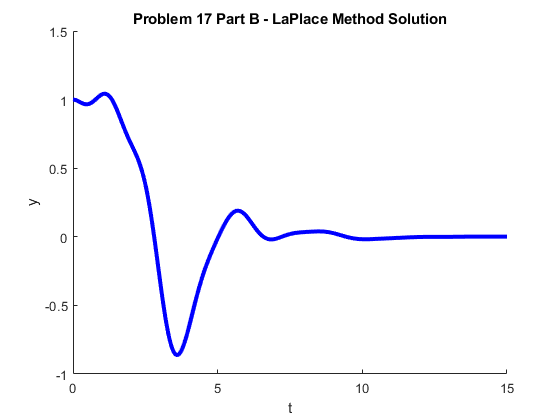

set(p17partB, 'linewidth', 3, 'color', 'b')
axis auto
xlabel t, ylabel y
title 'Problem 17 Part B - LaPlace Method Solution'
hold off

toc

Elapsed time is 2.768011 seconds.
